# Determinação da função de transferência de um motor CC - Gp(s) utilizando dados

Variáveis:

w - vel angular - saída

Theta - posição motor - saída

Entrada - tensão aplicada no motor

**Boas práticas**

clear all;      
clc;
close all;      %fecha janelas ativas

**Leitura de dados**

LeituraDados   %    le os dados do motor

N = length(in);                 %num de pontos de cada variavel
T = 10e-3;                      %taxa de amostragem
Duracao = N*T;                  %duracao de entrada

tempo = linspace(0,Duracao,N);  %vetor tempo

**Visualizando os dados**

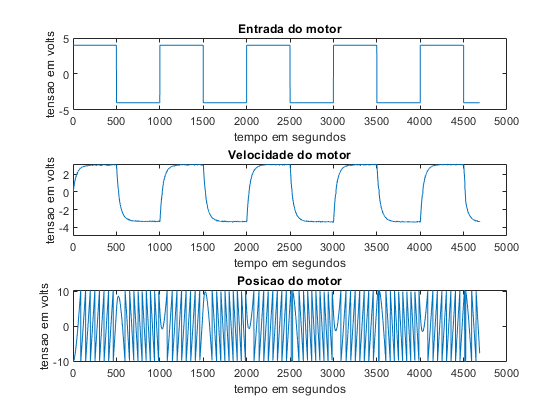

figure(1)

subplot(3,1,1); plot(in)    %visualiza entrada
xlabel('tempo em segundos')
ylabel('tensao em volts')
title('Entrada do motor')

subplot(3,1,2); plot(vel)   %visualiza velocidade
xlabel('tempo em segundos')
ylabel('tensao em volts')
title('Velocidade do motor')

subplot(3,1,3); plot(pos)   %visualiza posicao
xlabel('tempo em segundos')
ylabel('tensao em volts')
title('Posicao do motor')

**Modelo do sistema**

%Hipotese: o sistema é de primeira ordem, a forma canônica:



$$\mathrm{Gp}\left(s\right)=\frac{K}{\mathrm{Ts}+1}$$


% desejo determinar o K e a cte de tempo Ts

K=1;        %valor inicial para o ganho
T = 1;      %cte de tempo

Gp = tf(K,[T 1])

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




ym = lsim(Gp,in,tempo);     %simula a saida do modelo

figure(2)
plot(tempo, vel);   %dados reais - velocidade
hold;     %congela o grafico para sobrepor

Current plot held


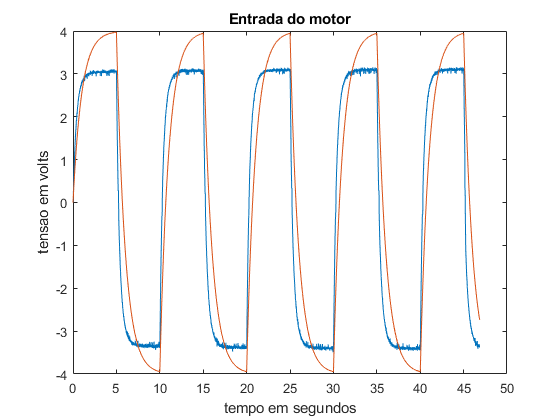

xlabel('tempo em segundos')
ylabel('tensao em volts')
title('Entrada do motor')
plot(tempo,ym);     %velociade simulada

**Determinar o ganho K e cte de tempo T visando minimizar o erro**

%quando a entra é 4 volts, a vel corresponde a 3.072
%a vel = K entrada --> K= vel/entrada

K=3.072/4   %ganho do sistema

Gp = tf(K,[T 1]);       %funcao d transf do modelo



## Modelo da malha de posicao

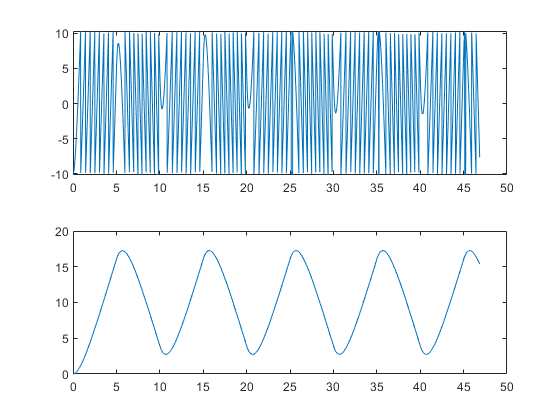

%Gppos = Gp*...

Gi = tf([1],[1 0]);     % integrador
Gppos = Gi*Gp;          %Modelo da posicao

ypos = lsim(Gppos,in,tempo);        %entrada aplicada ao modelo de posicao

figure(5)

subplot(2,1,1);plot(tempo,pos);     %dado real

subplot(2,1,2);plot(tempo,ypos);    %saida do modelo